clear
%%loading Rng seeds:Schnack_rng and Schnack_rng2
load("Schnack_unstable_rng_seed.mat")
S1 = Schnackenberg(0.2,0.5,47.5,690);
S1.rng_seed = Schnack_rng;

j_noise = logspace(-10,-5,40);

S1.maxt = 1;
S1tspan1 = S1.tspan;
[S1Lin_noise,~,S1Lin_noise_end] = Schnackenberg_Lin_change(S1,'noise',j_noise);


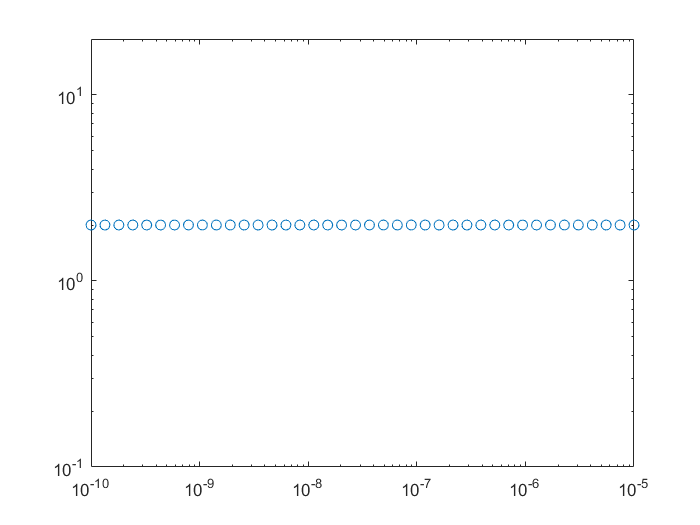

%gif_sol_surv(S1Lin_noise,S1tspan1);
[S1Lin_noise_mode,S1Lin_noise_maxProm] = Mode_test(S1Lin_noise_end,'MinProminence',0);
figure;
loglog(j_noise,S1Lin_noise_mode,'o');

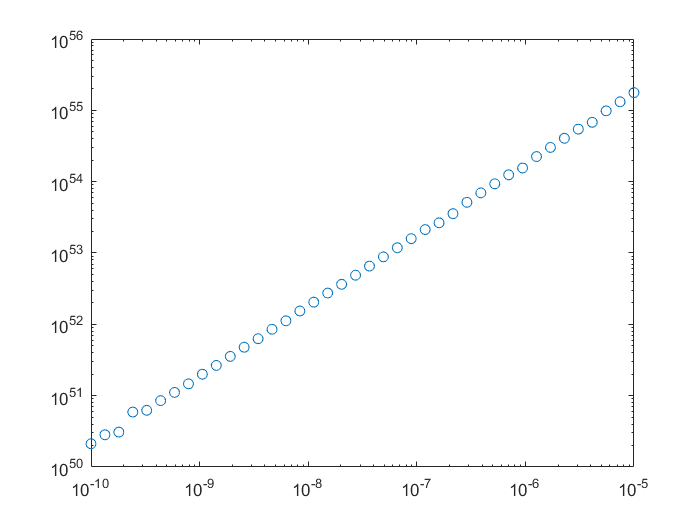

figure;
loglog(j_noise,S1Lin_noise_maxProm,'o')